# Experiment Pipeline for GCaMP and RCaMP Recording (no stim) on Pascal

Generated in MATLAB R2022b on 05-05-25 by Polina Cherepanova

Follow this script in order when running an experiment. **Don't connect the patchcord to the animal until it says to in the script!**

## **0. Turn Everything On**

- **Camera: **switch on bottom left side of rig hardware

- **Check that LEDs **are set to** "Trig" **(middle) and the dial is** not set to "off"**

## 1. Connect to Camera and Laser

Create connection to the camera and laser using the specified adaptors with the specified formats. It really doesn't like any other program connecting to either of the devices, even other Matlab windows, so close those before running this step.

% Camera
v = videoinput("hamamatsu", 1, "MONO16_BIN2x2_1152x1152_Fast");
v.ROIPosition = [0 160 576 238]*2;

src = getselectedsource(v);
src.OutputTriggerKindOpt2 = "exposure";
src.OutputTriggerPolarityOpt2 = "positive";
src.ExposureTime = 1/80;

% DAQ
dq = daq("ni");
dq.Rate = 2000; % scans/sec. Not important here yet
addinput(dq, "Dev1", "ai2", "Voltage"); % input channel receiving behavior cam frame time stamps

## 2. Calibrate Fiber Locations for Laser Stimulation

Execute the following BEFORE attaching patchcord to mouse headplate.

The automatic calibration GUI will both detect fibers and calculate where to send stimulation automatically.

% Call automatic calibration GUI
calibrationGUIAuto_OneImage;

## To check fiber detection calibration

% CHANGE FILE IF NEEDED
load('TranslatedCoords_050625.mat')

snpshot = getsnapshot(v);
num_rois = 12;
figure
imshow(snpshot);
hold on

for roi_n=1:num_rois
    circ(roi_n) = drawcircle('Center',[translated_coords(roi_n,1)-mids(1,1), translated_coords(roi_n, 2)-mids(1,2)],'Radius', translated_coords(roi_n,3), 'Color', 'blue');
    text(translated_coords(roi_n,1)-mids(1,1), translated_coords(roi_n, 2)-mids(1,2),sprintf('%d', roi_n), 'Color', 'white');
end

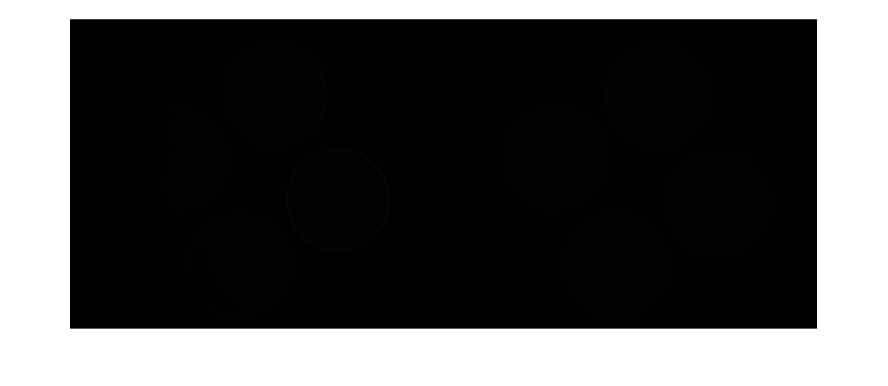

snpshot = getsnapshot(v);
num_rois = 12;
figure

imshow(snpshot);

## 5. Now Attach Patchcord to Mouse

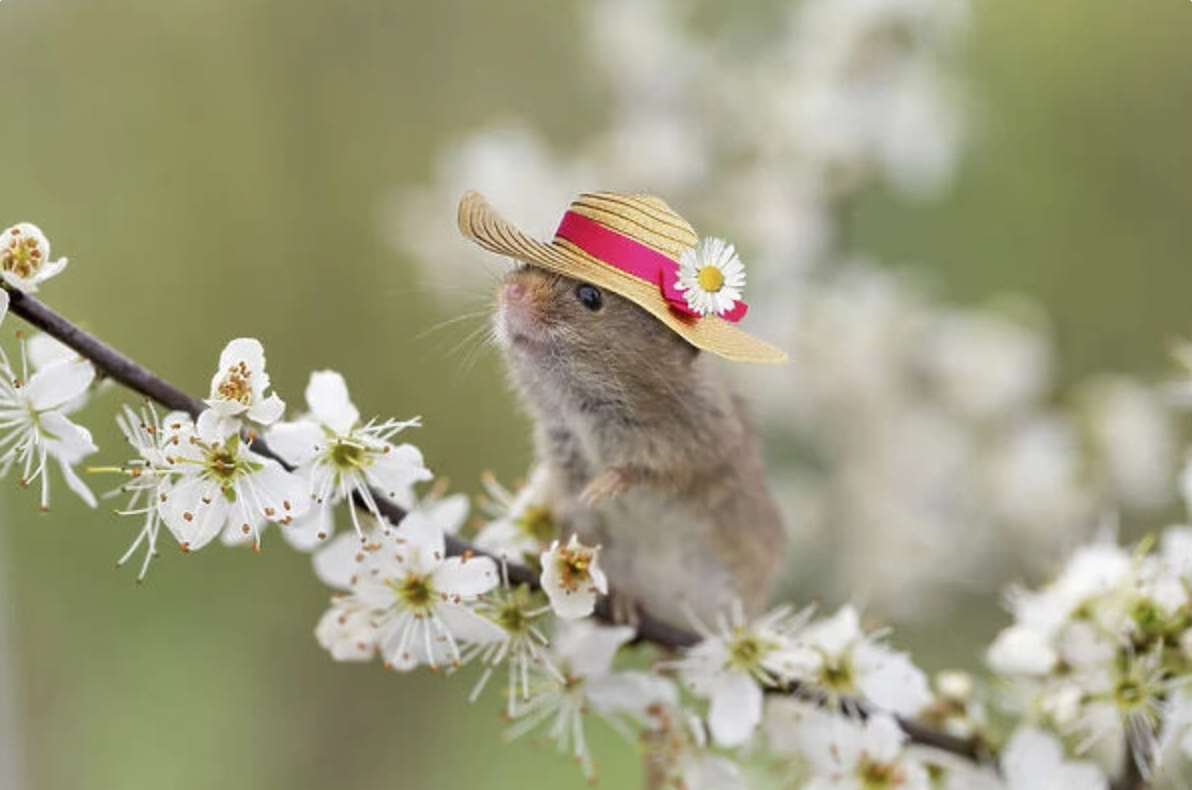

## 6a. Pull up Experimental GUI to Run Experiment!

This GUI allows you to set parameters and run your experiment.

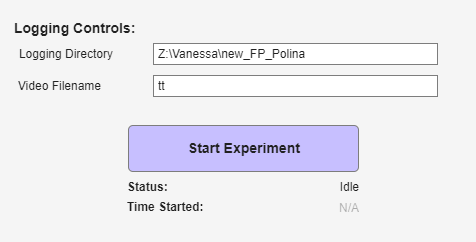

% Turn off connection to camera and laser first
clear v dq src

% Run experimental GUI:
ExperimentalGUI_TCNoStim;

## **7. Turn Everything Off**

- **Check that LEDs **are set to** "Trig" **(middle) and **no light is coming out of the patchcord**